# Applied Linear Regression in Matlab

## Calculating Pseudoinverses

We saw before how the general linear model $\mathbf{y}=\mathbf{X}\mathbf{\beta}+\mathbf{\epsilon}$ can be solved for $\mathbf{\beta}$ by finding the pseudoinverse $\mathbf{X}^+$ of the design matrix $\mathbf{X}$. Then our estimate for $\mathbf{\beta}$ can be found via matrix multiplication


$$\mathbf{\beta} = \mathbf{X}^+\mathbf{y}$$


For example, given a 5x3 design matrix $\mathbf{X}$

X = rand(5,3)

X =     0.4018    0.2400    0.4909
    0.0760    0.4173    0.4893
    0.2399    0.0497    0.3377
    0.1233    0.9027    0.9001
    0.1839    0.9448    0.3692


and a 5x1 response vector $\mathbf{y}$

y = rand(5,1)

y =     0.1112
    0.7803
    0.3897
    0.2417
    0.4039


we can estimate the parameters $\mathbf{\beta}$ using the `pinv` function to calculate the pseudoinverse.

beta = pinv(X)*y

beta =     0.0817
    0.1373
    0.4467


Matlab also offers the backslash operator (`\`) to solve linear systems.

beta = X \ y

beta =     0.0817
    0.1373
    0.4467


The backslash operator will choose the appropriate method for solving the system based on the structure of the coefficient matrix. If the coefficient matrix is square and full rank, an efficient variant of Gaussian elimination is selected. If the coefficient matrix is not square, pseudoinversion is used to find the least-squares solution.

## Simple Linear Regression

rng(2017); % set the Random Number Generator
x = linspace(1,15,100)';
y = 2*x + (x+randn(size(x))).^2;

Imagine you are given a set of 100 pairs of data $(x,y)$. We belive that $y$ is some function of $x$; can we identify this function using linear regression? If possible, we always start by plotting the data. In Matlab, we can use the `scatter` function to visualize individual points.

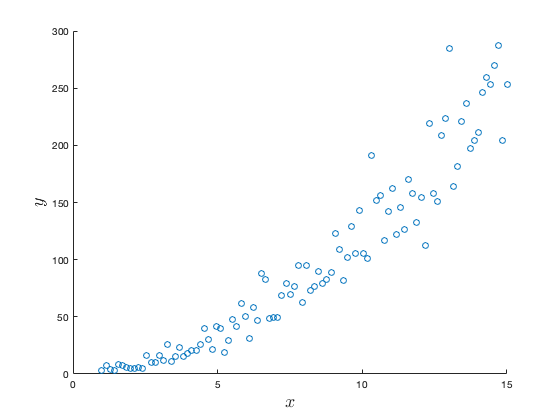

scatter(x,y)
xlabel('$$x$$','Interpreter','latex','FontSize',18)
ylabel('$$y$$','Interpreter','latex','FontSize',18)

Clearly there is some positive relationship between $y$ and $x$. Let's begin by fitting the simplest linear model


$$y = \beta_1 x$$


In this case, we only have one parameter to estimate ($\beta_1 $), and the design matrix $\mathbf{X}$ has only a single column with the 100 $x$ values.

X = [x];

Let's solve for the parameter estimates by pseudoinversion ($\mathbf{b} = \mathbf{X}^+\mathbf{y}$), or, equivalently, using the backslash operator.

beta = X \ y

beta = 13.3924

Let's plot our model on the same plot as the original data. First, we plot the data.

scatter(x,y)

Then, we tell Matlab to "hold on". This prevents Matlab from making a new figure for subsequent plots (until we tell it to "hold off").

hold on

Now we can plot a line with our model. The easiest way to multiply the design matrix by the parameter estimates.

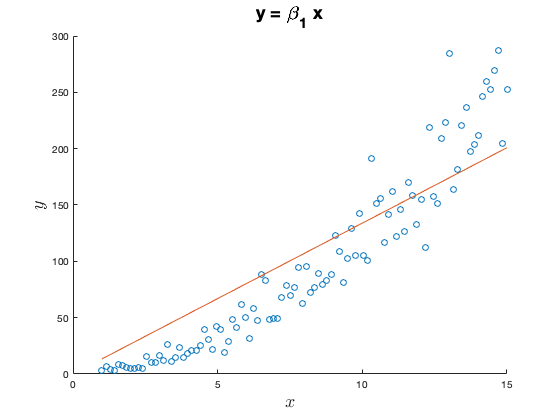

plot(x, X*beta)
title('y = \beta_1 x', 'FontSize',18)
xlabel('$$x$$','Interpreter','latex','FontSize',18)
ylabel('$$y$$','Interpreter','latex','FontSize',18)
hold off

This does not seem to be a great fit. Maybe we need an intercept term, making our model


$$y = \beta_0 +\beta_1 x$$


How do we add an intercept term? We want our final model to be of the form


$$\mathbf{y} = \mathbf{X}\left(\begin{array}{c}\beta_0  \\ \beta_1\end{array}\right)$$


This tells us that the design matrix $\mathbf{X}$ should be 


$$\left( \begin{array}{cc} 1 & x_1 \\ 1 & x_2 \\ \vdots& \vdots\\ 1 & x_n \end{array}\right)$$


The column of ones on the left allows the parameter $\beta_0$ to stand alone as an intercept. Let's construct this design matrix, solve for the parameters, and plot the new model.

X = [ones(size(x)) x];

We use the `ones` function to create a column of ones. The `ones` function accepts either two values giving the dimensions (e.g. `ones(3,4)`) or the size of a similar matrix (`ones(size(x))`). Yes, in case you're wondering, there is a `zeros` function.

beta = X \ y

beta =   -49.8172
   18.3332


The vector b now has two entries. The first is our estimate for $\beta_0 $, the second is the estimate for $\beta_1 $.

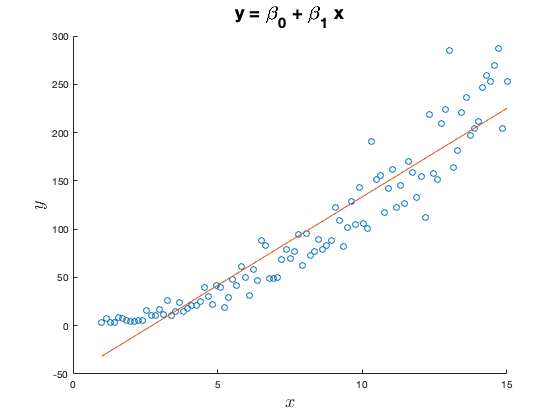

scatter(x,y)
hold on
plot(x, X*beta)
title('y = \beta_0 + \beta_1 x', 'FontSize',18)
xlabel('$$x$$','Interpreter','latex','FontSize',18)
ylabel('$$y$$','Interpreter','latex','FontSize',18)
hold off

To plot the line representing our model, we could have constructed the point manually as `beta(1) + beta(2).*x`. Notice two things. First, Matlab indexes vectors starting at one, so `beta(1)` is actually the estimate for $\beta_0$, not for $\beta_1$. Second, Matlab distinguishes between matrix multiplication (`*`) and element-by-element multiplication (`.*`).

This is still not a great fit. Based on the slight upward curve in the data, a quadratic model may be more appropriate. This model would be


$$y = \beta_0 + \beta_1 x + \beta_2 x^2$$


Fortunately, we can still fit quadratic polynomials (and, in fact, all polynomials) since **all polynomials are linear with respect to the parameters**. To fit a quadratic, we add a column to the design matrix that contains the square of each element in the vector `x`. (We will use the element-by-element exponentiation operator `.^` here; matrix exponentiation is completely different.)

X = [ones(size(x))  x  x.^2];
beta = X \ y

beta =     0.3349
    1.3816
    1.0595


Our vector of estimates now has three entries corresponding to $\beta_0 $, $\beta_1$, and $\beta_2$. Let's plot the quadratic model.

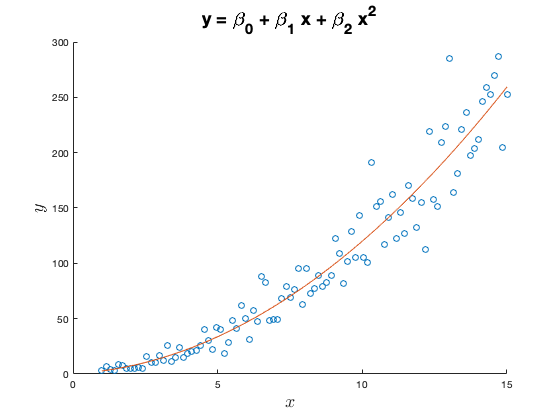

scatter(x,y)
hold on
plot(x, X*beta)
title('y = \beta_0 + \beta_1 x + \beta_2 x^2', 'FontSize',18)
xlabel('$$x$$','Interpreter','latex','FontSize',18)
ylabel('$$y$$','Interpreter','latex','FontSize',18)
hold off

That looks like a much better fit. These data appear to have a quadratic relationship.

## Linear Regression with `fitlm`

Matlab offers an easier method for fitting linear models -- the `fitlm` function. To use `fitlm`, we start by placing our data in a Matlab table.

tbl = table(x,y);
head(tbl) % head shows only a few entries of large tables

ans = 8×2 table
      x         y   
    ______    ______

         1     3.357
    1.1414    7.0774
    1.2828    3.6488
    1.4242    2.8731
    1.5657    8.2716
    1.7071    7.6963
    1.8485    5.3921
    1.9899    4.6634


Each variable given to the `table` function becomes a column in the table. The names of the columns are the names of the variables in the call to `table`. (If Matlab can't find the names, for example if you call `table(log(x), y+3)`, it names the columns "Var1", "Var2", etc.). You can change the names of an existing table by setting `tbl.Properties.VariableNames = {'name1', 'name2', ...}`. The column names are important, as we refer to variables by these names when specifying our linear model.

Now that we have our data in a table, we call `fitlm`.

model1 = fitlm(tbl, 'y ~ x')

model1 = Linear regression model:
    y ~ 1 + x

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)    -49.817      5.7739    -8.6281    1.1389e-13
    x               18.333     0.64288     28.517    3.0026e-49


Number of observations: 100, Error degrees of freedom: 98
Root Mean Squared Error: 26.2
R-squared: 0.892,  Adjusted R-Squared 0.891
F-statistic vs. constant model: 813, p-value = 3e-49

The first argument to `fitlm` is the table containing your data. The second argument is a string specifying the formula for the linear model. To specify a formula:

- Use a tilde to separate the response variable ($y$) from the input variables ($x_1$, $x_2$, etc.).

- Do not include the names of the parameters; only the input variables. For example, we say `'y ~ x'` not `'y ~ beta*x'`. The `fitlm` function adds a parameter for each term in the model.

- `fitlm` always adds an intercept by default. To turn off this behavior, call `fitlm` with the `'intercept'` option set to false, i.e. `fitlm(..., 'intercept', false)`.

- The names of the response and input variables must match column names in the table.

The output from `fitlm` begins by stating the specified model. Again, no parameters appear. If an intercept was added, it appears as a 1 (just like the column of ones in the design matrix). Next is a table of the fit parameters -- an estimate of each coefficient in the model, including the intercept. Along with providing the numerical value of the coefficient, `fitlm` also reports the standard error for the estimate. The standard errors are calculated using the degrees of freedom left over in the data. So long as the number of observations is greater than the number of variables, `fitlm` will be able to provide errors for each coefficient.

Using the standard errors, we can construct confidence intervals around the parameter estimates. It is important to know if the confidence interval includes zero. If so, then we cannot reject the possibility that the true value of the parameter is zero. If the true value is zero, we should not draw any inferences regarding the estimated coefficient, since we cannot statistically distinguish the parameter from zero. To help identify statistically significant parameters, `fitlm` performs a modified *t*-test on the parameter estimates. Using the *t*-statistic ("tStat" in the `fitlm` output), a *p*-value is calculated. Only those estimates with *p*-values below out significance threshold (e.g. 0.05) should be interpreted.

`fitlm` also provides summary statistics on the model as a whole. The most commonly used metris is the coefficient of determination ($R^2$). Values near one are ideal; however, there is not widely accepted cutoff for "good" vs. "bad" $R^2$ values. Instead, you should consider the *F*-statistic. This test measures if the model performs better than a null model -- a model that discards the inputs and returns only a constant value.

Finally, `fitlm` provides the root mean squared error (RMSE). This measures the accuracy of the model and summarizes how closely estimates made with the model match the observed responses. To calculate the RMSE, we use the observed responses ($y_i$) and the predicted responses ($\hat{y_i}$) from our model on the corresponing inputs ($x_i$). Then the RMSE is


$$\mathrm{RMSE} = \sqrt{\frac{1}{n}\sum_{i=1}^m(y_i-\hat{y_i})^2$$


The RMSE is the square root of the average penalty (the squared error) found during the least squares estimation.

Let's use `fitlm` to fit our quadratic model. 

model2 = fitlm(tbl, 'y ~ x^2')

model2 = Linear regression model:
    y ~ 1 + x + x^2

Estimated Coefficients:
                   Estimate      SE        tStat        pValue  
                   ________    _______    ________    __________

    (Intercept)    0.33485      8.0944    0.041369       0.96709
    x               1.3816      2.3069     0.59887       0.55065
    x^2             1.0595     0.14057       7.537    2.5514e-11


Number of observations: 100, Error degrees of freedom: 97
Root Mean Squared Error: 20.9
R-squared: 0.932,  Adjusted R-Squared 0.931
F-statistic vs. constant model: 667, p-value = 2.1e-57

For convenience, adding a quadratic term in the `fitlm` formula expands to include the linear term. This behavior can be disabled using the `'purequadratic'` option.

## Exploratory Data Analysis with Linear Models

We can use linear modeling to identify factors that significantly affect an outcome. For example, lets use Matlab's builtin set of simulated hospital records.

load hospital_records

Error using load
Unable to read file 'hospital_records'. No such file or directory.

hospital(1:10,:)

We want to identify any factors (sex, age, weight, or smoking) that increase blood pressure. We will build a linear model that combines these factors to predict blood pressure. First, let's average the systolic and diastolic blood pressures into a single value that we can use as our response variable.

hospital.meanBP = mean(hospital.BloodPressure,2);
hospital(1:10,:)

We added another column, "meanBP" to the `hospital` table. The second argument to mean tells the function to calculate the means along the second dimension. This gives us the mean for each row.

Now we build and fit a linear model using fitlm.

fitlm(hospital, 'meanBP ~ Sex + Age + Weight + Smoker')

Looking at the coefficient estimates, we find that only smoking is a significant predictor. The coefficient is 10.1, so smokers on average have a blood pressure that is 10 mmHg higher than non-smokers.

Be careful in interpreting the intercept of this model. The intercept is the response value when all inputs are zero. For this example, all zero inputs would be a female non-smoker of age zero that weighs nothing. Instead, we can find an average blood pressure for a 30 year old, 100 pound female nonsmoker as


$$\mathrm{BP} = 97.1 + 0.51(0) + 0.058(30) - 0.00080(100) + 10.1(0) = 98.8$$


For a 50 year old, 260 pound male smoker, the estimate would be


$$\mathrm{BP} = 97.1 + 0.51(1) + 0.058(50) - 0.00080(260) + 10.1(1) = 110.4$$


## Interactions

rng(61112);

conc_A = rand(15,1);
conc_B = rand(15,1);
response = 3.*conc_A + 4.5.*conc_B + 12.5.*conc_A.*conc_B + 0.5.*randn(15,1);
drug = table(response, conc_A, conc_B);

Linear models can test for significant interactions between variables. To include interactions between variables $x_i$ and $x_j$, we add a new term that is the product of the two variables ($x_ix_j$). We choose multiplication to combine the variables since this interaction term will only be nonzero when **both** variables are nonzero; thus, the interaction is suppressed when either variable is not observed.

Interactions are commonly used to test for *synergy* between drugs. For drugs to synergize, the observed response must be greater than the expected additive effects of the two drugs alone. (If the drugs response is lower than expected, the drugs are *antagonistic*.)

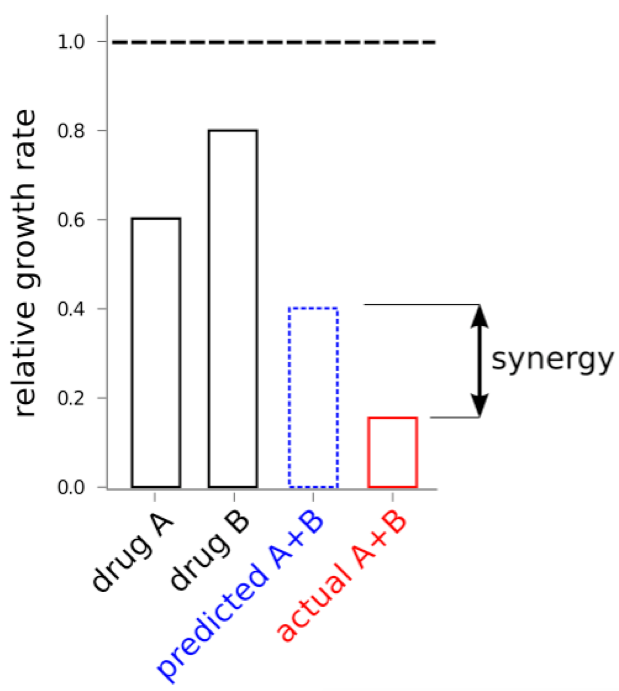

We modeled the response to the drug ($y$) as a linear combination of the two drugs independently plus an interaction term:


$$y = \beta_0 + \beta_1 c_1 + \beta_2c_2 + \beta_{12}c_1c_2$$


where $c_1$ is the concentration of drug 1 (or log-concentration, as dose responses are often log-linear), and $c_2$ is the concentration of drug 2. The intercept ($\beta_0$) is the basal response of the assay when neither drug is added. The parameter $\beta_{12}$ corresponds to the strength of the interaction. If we fit the above model and find a significant, nonzero $\beta_{12}$ term, we can conclude that some nonlinear interaction exists between the drugs.

Let's test for synergy with the following drug response data (with concentration in log scale).

drug

In `fitlm` formulas, interactions are specified by combining the two variable names with a colon (`x1:x2`). As a shortcut, we can add both linear terms and an interaction term using the * operator. The formula `response ~ x1 + x2 + x1:x2 `is equivalent to the formula `response ~ x1 * x2`.

First, let's fit a linear model without interaction.

model_lin = fitlm(drug, 'response ~ conc_A + conc_B')

We would like to plot the data and our model. Unfortunately, the multiple input variables make visualization difficult. Instead, we can get a sense for our model's accuracy by plotting the observed response values vs. the model's predicted response values. (We use the predict function to find the predicted values from a fitted model and the original data table. We also add a diagonal line corresponding to perfect correlation.)

scatter(drug.response, predict(model_lin,drug))
xlabel('Predicted');
ylabel('Observed');
title('Linear Terms Only');
hold on
plot([0 17], [0 17])
hold off

This isn't a bad model fit, but it can clearly be improved. Maybe the interaction terms will help.

model_int = fitlm(drug, 'response ~ conc_A * conc_B')

The coefficient of the interaction term is statistically significant at *p *< 0.05. The coefficient is also positive, indicating synergy between the drugs. Let's see if taking the synergy into account improves our predictions.

scatter(drug.response, predict(model_int,drug))
xlabel('Predicted');
ylabel('Observed');
title('Linear and Interaction Terms');
hold on
plot([0 17], [0 17])
hold off

The model with the interaction term is a better predictor of the drug response.